## Machine Learning for Engineers: [ImbalancedData](https://www.apmonitor.com/pds/index.php/Main/ImbalancedData)

- Description: Identify imbalanced data and use undersampling or oversampling to improve the machine learning classification results


%create balanced data
T = readtable('Balanced_Data.xlsx')

T = 4000×3 table
       X          Y       label
    _______    _______    _____

     7.7574     4.1443      1  
    -4.8757    -1.4821      0  
    -4.5482     2.4708      0  
    -1.1726     5.8463      0  
    -2.8745    0.49394      0  
     6.4396      6.851      1  
     4.0846     6.2339      1  
     5.6163      2.066      1  
    -9.1604     3.9382      0  
     8.4615     1.4392      1  
    -1.6242     6.4938      0  
     3.6466     3.8637      1  
    -2.8658     2.0771      0  
      3.621     2.7725      1  
    -6.2231     1.1858      0  
     10.217     5.1664      1  


T.X(5,1)

ans = -2.8745

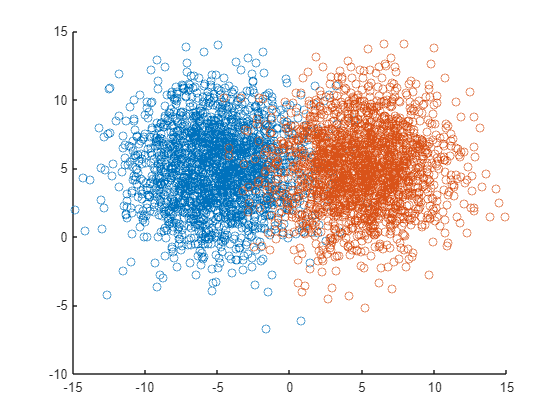

%Plot the data 
for cv = 0:1
    row = find(T.("label") == cv);
    scatter(T.X(row,1),T.Y(row,1))
    hold on
end 

hold off


%%Undersample 
U = readtable('Undersample_Data.xlsx')

U = 2050×3 table
       X           Y       label
    ________    _______    _____

    -0.96502     4.1451      0  
     -3.5169     6.3719      0  
    0.033934     2.0407      0  
     -3.5566     1.9801      0  
     -5.8238     3.0606      0  
     -5.1391      4.494      0  
     -6.1753     9.3945      0  
     -8.1733     5.6969      0  
     -3.2481     3.7574      0  
     -2.2461     5.5884      0  
     -1.7647     9.2237      0  
      -13.06     2.7036      0  
     -7.7815     8.7267      0  
     -3.6557     6.7679      0  
     -12.552     7.5605      0  
      -9.142    -3.6037      0  



%%Logistic Regression 
%%mnrfit([U.Y, U.X],U.('label'))
model = fitclinear([U.X,U.Y], U.label)

model =   ClassificationLinear
      ResponseName: 'Y'
        ClassNames: [0 1]
    ScoreTransform: 'none'
              Beta: [2×1 double]
              Bias: -1.8242
            Lambda: 4.8780e-04
           Learner: 'svm'


  Properties, Methods


maxX = max(U.X) + 1

maxX = 13.7303

minX = min(U.X) - 1

minX = -15.8206

maxY = max(U.Y) + 1

maxY = 15.0322

minY = min(U.Y) - 1

minY = -7.6931

[x1grid, x2grid] = meshgrid(minX:0.01:maxX, minY:0.01:maxY)

x1grid =   -15.8206  -15.8106  -15.8006  -15.7906  -15.7806  -15.7706  -15.7606  -15.7506  -15.7406  -15.7306  -15.7206  -15.7106  -15.7006  -15.6906  -15.6806  -15.6706  -15.6606  -15.6506  -15.6406  -15.6306  -15.6206  -15.6106  -15.6006  -15.5906  -15.5806  -15.5706  -15.5606  -15.5506  -15.5406  -15.5306  -15.5206  -15.5106  -15.5006  -15.4906  -15.4806  -15.4706  -15.4606  -15.4506  -15.4406  -15.4306  -15.4206  -15.4106  -15.4006  -15.3906  -15.3806  -15.3706  -15.3606  -15.3506  -15.3406  -15.3306
  -15.8206  -15.8106  -15.8006  -15.7906  -15.7806  -15.7706  -15.7606  -15.7506  -15.7406  -15.7306  -15.7206  -15.7106  -15.7006  -15.6906  -15.6806  -15.6706  -15.6606  -15.6506  -15.6406  -15.6306  -15.6206  -15.6106  -15.6006  -15.5906  -15.5806  -15.5706  -15.5606  -15.5506  -15.5406  -15.5306  -15.5206  -15.5106  -15.5006  -15.4906  -15.4806  -15.4706  -15.4606  -15.4506  -15.4406  -15.4306  -15.4206  -15.4106  -15.4006  -15.3906  -15.3806  -15.3706  -15.3606  -15.3506  -15.3406

x2grid =    -7.6931   -7.6931   -7.6931   -7.6931   -7.6931   -7.6931   -7.6931   -7.6931   -7.6931   -7.6931   -7.6931   -7.6931   -7.6931   -7.6931   -7.6931   -7.6931   -7.6931   -7.6931   -7.6931   -7.6931   -7.6931   -7.6931   -7.6931   -7.6931   -7.6931   -7.6931   -7.6931   -7.6931   -7.6931   -7.6931   -7.6931   -7.6931   -7.6931   -7.6931   -7.6931   -7.6931   -7.6931   -7.6931   -7.6931   -7.6931   -7.6931   -7.6931   -7.6931   -7.6931   -7.6931   -7.6931   -7.6931   -7.6931   -7.6931   -7.6931
   -7.6831   -7.6831   -7.6831   -7.6831   -7.6831   -7.6831   -7.6831   -7.6831   -7.6831   -7.6831   -7.6831   -7.6831   -7.6831   -7.6831   -7.6831   -7.6831   -7.6831   -7.6831   -7.6831   -7.6831   -7.6831   -7.6831   -7.6831   -7.6831   -7.6831   -7.6831   -7.6831   -7.6831   -7.6831   -7.6831   -7.6831   -7.6831   -7.6831   -7.6831   -7.6831   -7.6831   -7.6831   -7.6831   -7.6831   -7.6831   -7.6831   -7.6831   -7.6831   -7.6831   -7.6831   -7.6831   -7.6831   -7.6831   -7.6831

# QUESTION FOR AYCAN AND JIANHAO: How can we create a contour plot using meshgrid? 

%%%[xx, yy] = meshgrid(x1grid, x2grid);

Error using repmat
Requested array exceeds the maximum possible variable size.

Error in meshgrid (line 61)
        xx = repmat(xrow,size(ycol));

Related documentation

grid = [x1grid(:),x2grid(:)];
yp = predict(model, grid) 

zz = reshape(yp, size(x1grid))
figure('Units', 'normalized','Position',[0.2,0.1,0.4,0.6]);
contour(x1grid, x2grid, zz, 'Linestyle', 'none');
hold on; 
%Plot the data 
for cv = 0:1
    row = find(U.("label") == cv);
    scatter(U.X(row,1),U.Y(row,1))
    hold on
end 

hold off

axis tight; 
title('Imbalanced Classification');



%Plot the data 
% for cv = 0:1
%     row = find(U.("label") == cv);
%     scatter(T.X(row,1),T.Y(row,1))
%     hold on
% end 
% 
% hold off
% 
% 
% scatter(x1,y1,'blue');
% hold on;
% scatter(x2, y2, 'r');



% 
% max2 = max(max(y1),max(y2));
% min2 = min(min(y1),min(y2));
% 
% x1grid = min1:0.1:max1
% x2grid = min2:0.1:max2


%%Create MeshGrid 
% [xx,yy] = meshgrid(x1grid,x2grid)
% r1 = xx(:)
% r2 = yy(:);
% grid = [r1 r2]

## Fit to model

%%%%TODO::: Stuck here -> unsure of data processing in MATLAB with regards
%%%%to make_blob function 
% features = rand(1000,2) 
% labels = [ones(500,1);ones(500,1)*2];
% scatter(features(:,1),features(:,2),[],labels); 
% label = population(randperm(2000))